# CT Segmentation 

Team SPECT

Mei Li Luisa Cham Perez | A01139386

Marcela Enriquez López | A01570502

Natalia Verónica Flores Del Río | A01570472

Ana Lucía Soria Cardona | A00827565

Graciel Alejandra Rincon Lopez | A00827075

## Chest

f=imread("CT_CHEST.jpeg");
f=double(f(:,:,1));
f=f/max(max(f));
imshow(f)
title('Original Picture')

## Otsu Segmentation

%Roberts Operator
dxp=[0,1;-1,0];
dyp=[1,0;0,-1];

% Disk for clossing labels
diskse11= strel('disk',11);

thr = graythresh(f);         %define threshold 
seg1 = f > thr;             %
imshow(seg1,[])  %black and white image contrast that is placed under the original image 
title('Black and White image contrast placed unedr the original picture')
dxp=[0,1;-1,0];
dyp=[1,0;0,-1];  % gradiente en y


image_open = imopen(seg1,diskse11);
image_close = imclose(seg1,diskse11);

imshow(image_open)
title('Open Image')

imshow(image_close)
title('Close Image')

cc = bwconncomp(image_close == 0,4);
L = labelmatrix(cc);
imshow(L,[])
title('Label Matrix image - Otsu Method')

rightlung= L==6;
% 6 for right lung, 7 for left lung
imshow(rightlung)
title('Right lung - Otsu Method')

B = labeloverlay(f,rightlung);
imshow(B)
title("Otsu Method Right Lung overlay")

## K-means Segmentation

% 2 class
[L,Centers] = imsegkmeans(uint8(255*f),2);
B = labeloverlay(f,L);
imshow(L,[])
colormap('hot')
title("Labeled Image, K=2")


%First label
subplot(1,1,1)
label_one = L == 1;
imshow(label_one)
title('Label 1')
% remove false negatives wiht imclose
diskse = strel('disk',1);
label_close_one = imclose(label_one,diskse);
imshow(label_close_one)
title('Removing False negatives with imclose')


cc = bwconncomp(label_close_one,4);
labeled = labelmatrix(cc);
imshow(labeled,[])
title('Label Matrix image - K=2')
colormap('cool')
rightlung = labeled ==10;
imshow(rightlung)    % 10 for right lung
title('Right lung, K=2')

B = labeloverlay(f,rightlung);
imshow(B)
title("K-means (K=2) Method Right Lung overlay")

% 3 class
[L,Centers] = imsegkmeans(uint8(255*f),3);
B = labeloverlay(f,L);
imshow(L,[])
colormap('hot')
title("Labeled Image, K=3")

%First label
subplot(1,1,1)
label_one = L == 1;
imshow(label_one)
title('Label 1')
% remove false negatives wiht imclose
diskse = strel('disk',1);
label_close_one = imclose(label_one,diskse);
imshow(label_close_one)
title('Removing False negatives with imclose')

cc = bwconncomp(label_close_one,4);
labeled = labelmatrix(cc);
imshow(labeled,[])
title('Label Matrix image - K=3')
colormap('cool')

rightlung = labeled ==11;
imshow(rightlung)    
title('Right lung, K=3')

B = labeloverlay(f,rightlung);
imshow(B)
title("K-means (K=3) Method Right Lung overlay")

% 4 class
[L,Centers] = imsegkmeans(uint8(255*f),4);
B = labeloverlay(f,L);
imshow(L,[])
colormap('hot')
title("Labeled Image, K=4")

%First label
subplot(1,1,1)
label_one = L == 1;
imshow(label_one)
title('Label 1')
% remove false negatives wiht imclose
diskse = strel('disk',1);
label_close_one = imclose(label_one,diskse);
imshow(label_close_one)
title('Removing False negatives with imclose')

cc = bwconncomp(label_close_one,4);
labeled = labelmatrix(cc);
imshow(labeled,[])
title('Label Matrix image - K = 4')
colormap('cool')

rightlung = labeled ==14;
imshow(rightlung)    
title('Right lung, K=4')

B = labeloverlay(f,rightlung);
imshow(B)
title("K-means (K=4) Method Right Lung overlay")

## Watershed using Canny

edgeC = edge(f,'Canny');
imshow(edgeC,[])
title('Edges with Canny')
D = bwdist(edgeC);
imshow(D,[])
title('Distance Transform of Binary Image')
mesh(D)
L = watershed(D);

edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same'));
imshow(f+edgemap,[0,1]);
title('Edgemap')

imshow(L,[])
colormap('cool')
title('Watershed Segmentation matrix')

%The lung is made of several components. We must merge the labels
RightLung = L == 241 | L == 124| L==208|L==239|L==236|L==297|L ==277 | L== 283 | L ==392 | L == 253;

imshow(RightLung,[])
title('Right Lung using Watershed (Canny)')

RightLung_Close = imclose(RightLung,diskse);   % Eliminates edges and creates a solid figure
imshow(RightLung_Close)
title('Close Right Lung Watershed (Canny)')

B = labeloverlay(f,RightLung_Close);
imshow(B)
title("Right Lung overlay - Watershed (Canny)")

% Remove false positives with imopen
label_lung = imopen(RightLung_Close,diskse11);
imshow(label_lung)
title('Removing false positives with imopen')

B = labeloverlay(f,label_lung);
imshow(B)
title("Final Right Lung overlay - Watershed (Canny)")

## Watershed using Log

edgeC = edge(f,'log');
imshow(edgeC,[])
title('Edges with log')
D = bwdist(edgeC);
imshow(D,[])
title('Distance Transform of Binary Image')
mesh(D)
L = watershed(D);

edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same'));
imshow(f+edgemap,[0,1]);
title('Edgemap')

imshow(L,[])
colormap('cool')
title('Watershed Segmentation matrix with Log')

%The lung is made of several components. We must merge the labels
RightLung = L == 199|L == 368|L==252|L==303|L==364|L==362|L ==361| L==438|L ==383|L==419|L==419|L==427|L==332;

imshow(RightLung,[])
title('Right Lung using Watershed (Log)')

RightLung_Close = imclose(RightLung,diskse);   % Eliminates edges and creates a solid figure
imshow(RightLung_Close)
title('Close Right Lung Watershed (Log)')

B = labeloverlay(f,RightLung_Close);
imshow(B)
title("Right Lung overlay - Watershed (Log)")

% Remove false positives with imopen
label_lung = imopen(RightLung_Close,diskse11);
imshow(label_lung)
title('Removing false positives with imopen')

B = labeloverlay(f,label_lung);
imshow(B)
title("Final Right Lung overlay - Watershed (Log)")


## Hip

f=imread("CT-abdomenal.jpg");
f=double(f(:,:,1));
f=f/max(max(f));
imshow(f)
title('Original Picture')

## Otsu Segmentation

%Roberts Operator
dxp=[0,1;-1,0];
dyp=[1,0;0,-1];

% Disk for clossing labels
diskse11= strel('disk',1);

thr = graythresh(f)         %define threshold 
seg1 = f > thr;             %
imshow(seg1,[])             %black and white image contrast that is placed under the original image 
title(' black and white image contrast that is placed under the original image')
dxp=[0,1;-1,0];
dyp=[1,0;0,-1];  % gradiente en y


image_open = imopen(seg1,diskse11);
image_close = imclose(seg1,diskse11);

imshow(image_open)
title('Open Image')

imshow(image_close)
title('Close Image')

cc = bwconncomp(image_close == 0,4);
L = labelmatrix(cc);
imshow(L,[])
title('Label Matrix image')

% leftHip = L == ;
% imshow(leftHip)
% title('Left Hip)


## K-means Segmentation

% 2 class
[L,Centers] = imsegkmeans(uint8(255*f),2);
B = labeloverlay(f,L);
imshow(L,[])
colormap('hot')
title("Labeled Image, K=2")


%First label
subplot(1,1,1)
label_one = L == 1;
imshow(label_one)
title('Label 1')

% remove false negatives wiht imclose
diskse = strel('disk',1);
label_close_one = imclose(label_one,diskse);
imshow(label_close_one)
title('Removing False negatives with imclose')

%second label
label_two = L == 2;
% remove false negatives wiht imclose
label_close_two = imclose(label_two,diskse);
imshow(label_close_two)
title('Label 2')


cc = bwconncomp(label_close_two,4);
labeled = labelmatrix(cc);
imshow(labeled,[])
title('Label Matrix image - K=2')
colormap('cool')

leftHip = labeled ==48;
imshow(leftHip)    
title('Left Hip, K=2')

B = labeloverlay(f,leftHip);
imshow(B)
title("K-means (K=2) Method Left Hip overlay")

% 3 class
[L,Centers] = imsegkmeans(uint8(255*f),3);
B = labeloverlay(f,L);
imshow(L,[])
colormap('hot')
title("Labeled Image, K=3")

%First label
subplot(1,1,1)
label_one = L == 1;
imshow(label_one)
title('Label 1')
% remove false negatives wiht imclose
diskse = strel('disk',1);
label_close_one = imclose(label_one,diskse);
imshow(label_close_one)
title('Removing False negatives with imclose')


%second label
label_two = L == 2;
% remove false negatives wiht imclose
label_close_two = imclose(label_two,diskse);
imshow(label_close_two)
title('Label 2')

%Third label
label_three = L == 3;
% remove false negatives wiht imclose
label_close_three = imclose(label_three,diskse);
imshow(label_close_three)

cc = bwconncomp(label_close_three,4);
labeled = labelmatrix(cc);
imshow(labeled,[])
title('Label Matrix image - K=3')
colormap('cool')

leftHip = labeled ==416;
imshow(leftHip)    
title('Left Hip, K=3')

B = labeloverlay(f,leftHip);
imshow(B)
title("K-means (K=3) Method Left Hip overlay")

% 4 class
[L,Centers] = imsegkmeans(uint8(255*f),4);
B = labeloverlay(f,L);
imshow(L,[])
colormap('hot')
title("Labeled Image, K=4")

%First label
subplot(1,1,1)
label_one = L == 1;
imshow(label_one)
title('Label 1')
% remove false negatives wiht imclose
diskse = strel('disk',1);
label_close_one = imclose(label_one,diskse);
imshow(label_close_one)
title('Removing False negatives with imclose')

%second label
label_two = L == 2;
% remove false negatives wiht imclose
label_close_two = imclose(label_two,diskse);
imshow(label_close_two)
title('Label 2')

%Third label
label_three = L == 3;
% remove false negatives wiht imclose
label_close_three = imclose(label_three,diskse);
imshow(label_close_three)
title('Label 3')


cc = bwconncomp(label_close_three,4);
labeled = labelmatrix(cc);
imshow(labeled,[])
title('Label Matrix image - K = 4')
colormap('cool')

leftHip = labeled == 60;
imshow(leftHip)    
title('Left Hip, K=4')

B = labeloverlay(f,leftHip);
imshow(B)
title("K-means (K=4) Method Left Hip overlay")

## Watershed using Canny

edgeC = edge(f,'Canny');
imshow(edgeC,[])
title('Edges with Canny')
D = bwdist(edgeC);
imshow(D,[])
title('Distance Transform of Binary Image')
mesh(D)
L = watershed(D);

edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same'));
imshow(f+edgemap,[0,1]);
title('Edgemap')

imshow(L,[])
colormap('cool')
title('Watershed Segmentation matrix')

%The hip is made of several components. We must merge the labels
leftHip = L == 479 | L == 495| L==459|L==399|L==433|L==413|L ==452 | L== 464 | L ==531 | L == 512|L==527|L==505;

imshow(leftHip,[])
title('Left Hip using Watershed (Canny)')

leftHip_Close = imclose(leftHip,diskse);   % Eliminates edges and creates a solid figure
imshow(leftHip_Close)
title('Close Left Hip Watershed (Canny)')

B = labeloverlay(f,leftHip_Close);
imshow(B)
title("Left Hip overlay - Watershed (Canny)")

% Remove false positives with imopen
label_hip = imopen(leftHip_Close,diskse11);
imshow(label_hip)
title('Removing false positives with imopen')

B = labeloverlay(f,label_hip);
imshow(B)
title("Final Left Hip overlay - Watershed (Canny)")

## Watershed using Log

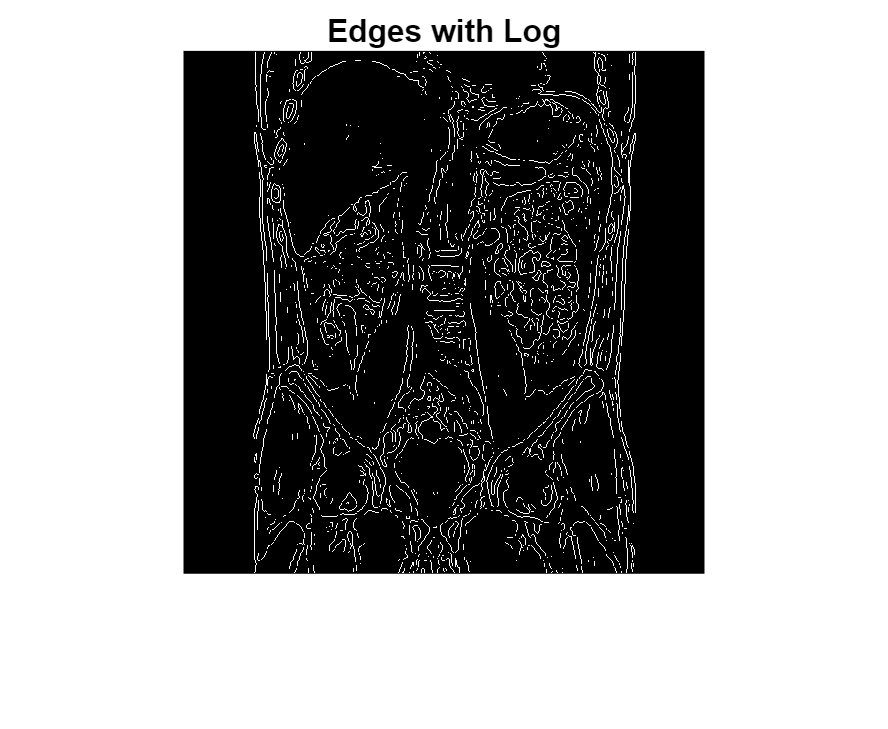

edgeC = edge(f,'log');
imshow(edgeC,[])
title('Edges with Log')

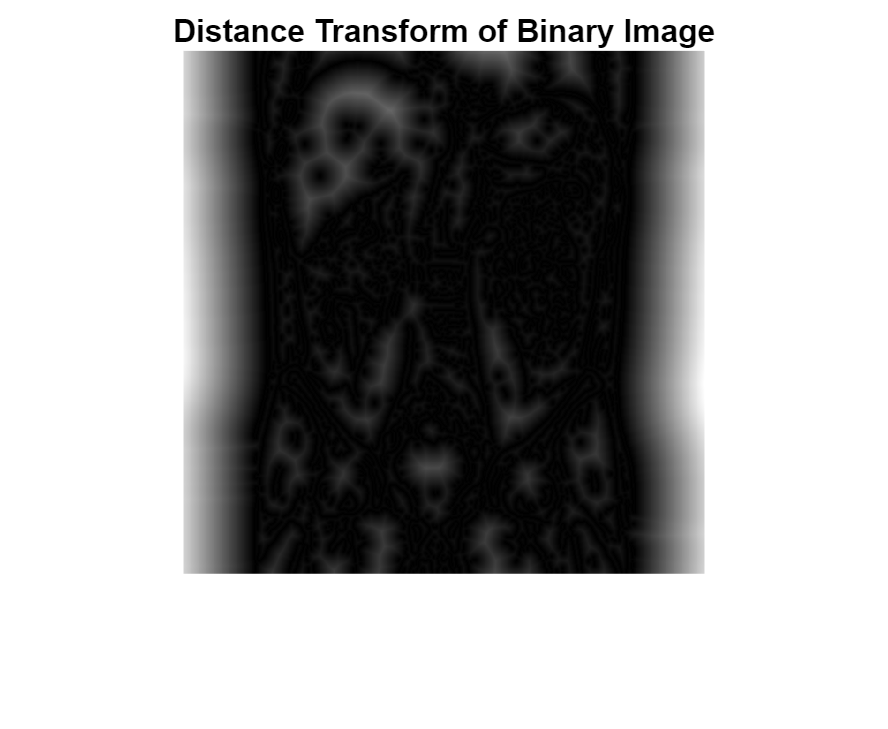

D = bwdist(edgeC);
imshow(D,[])
title('Distance Transform of Binary Image')

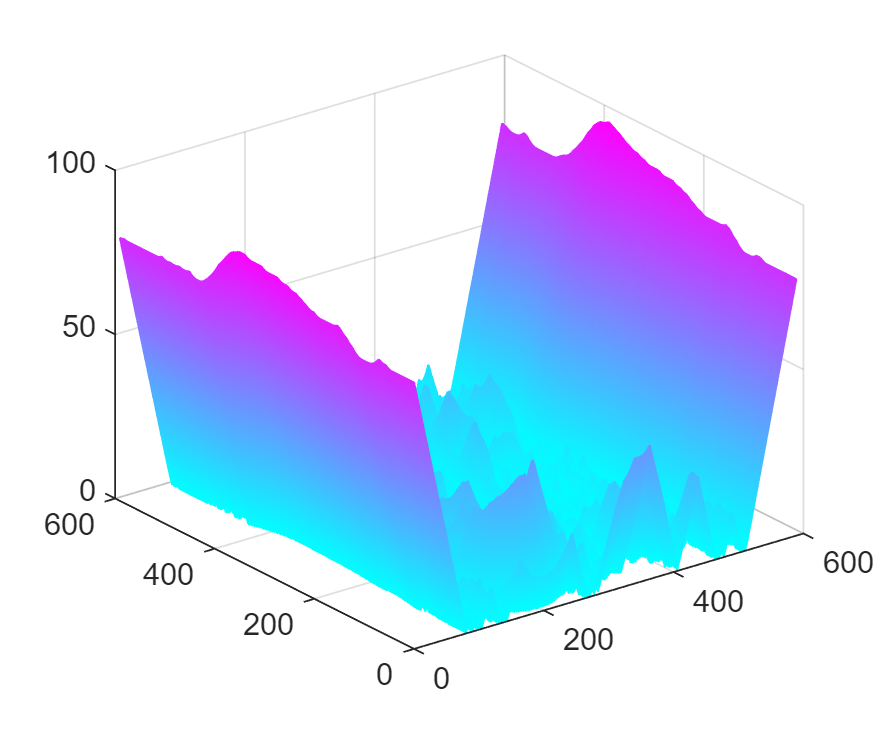

mesh(D)

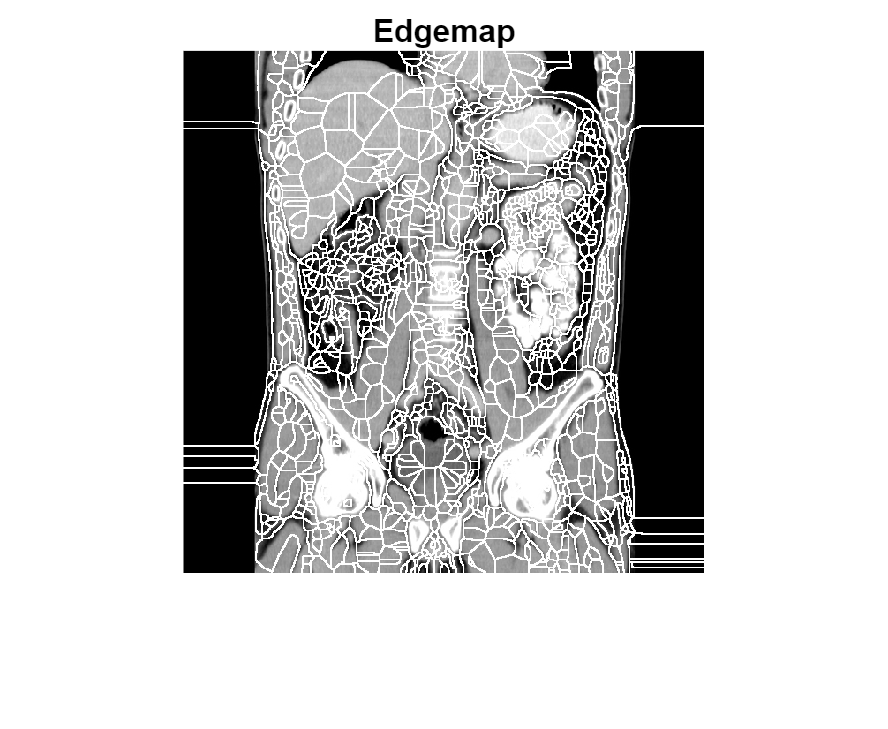

L = watershed(D);

edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same'));
imshow(f+edgemap,[0,1]);
title('Edgemap')

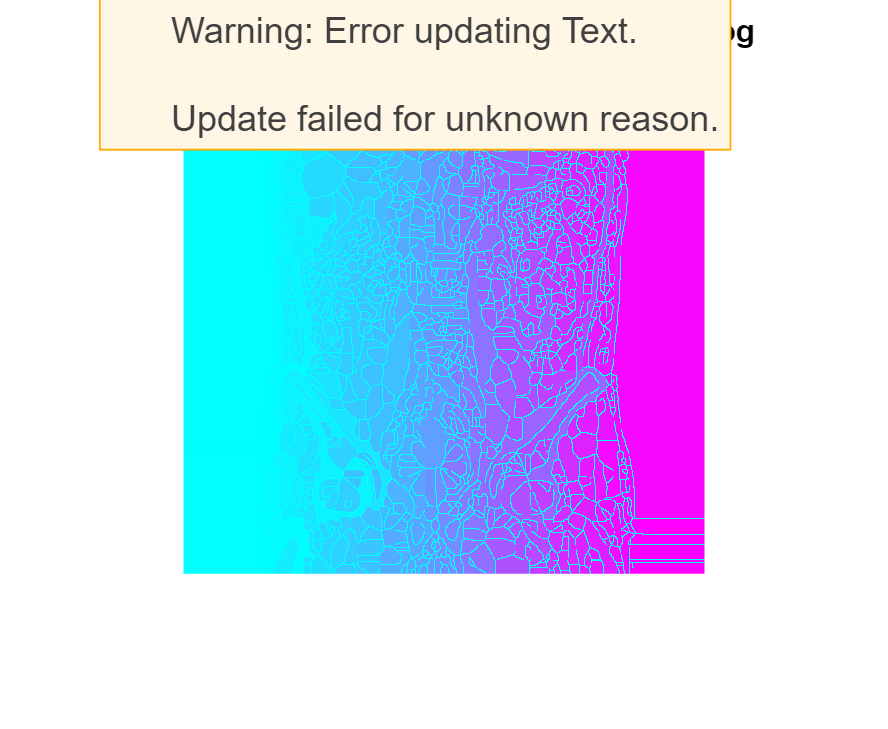


imshow(L,[])
colormap('cool')
title('Watershed Segmentation matrix with Log')

826 878 855 838 824 803 788 777 759 804 851 901 885 910 766 761

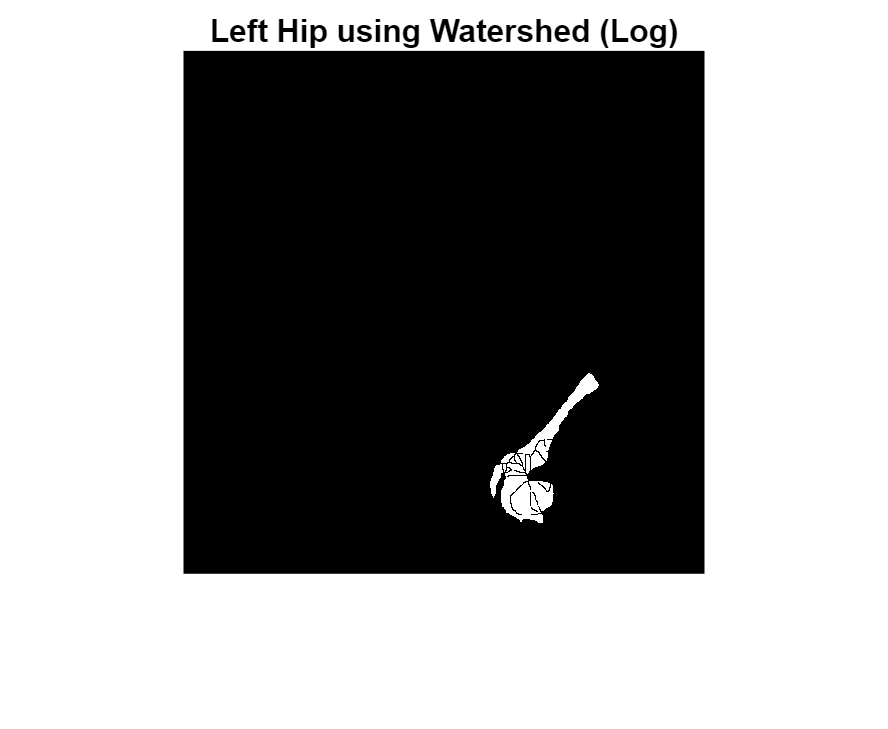

%The Hip is made of several components. We must merge the labels
leftHip = L==826|L==878|L==855|L==838|L==824|L==803|L==788|L==777|L==759|L==804|L==851|L==901|L==885|L==910|L==766|L==761|L==729|L==767|L==769|L==775;

imshow(leftHip,[])
title('Left Hip using Watershed (Log)')

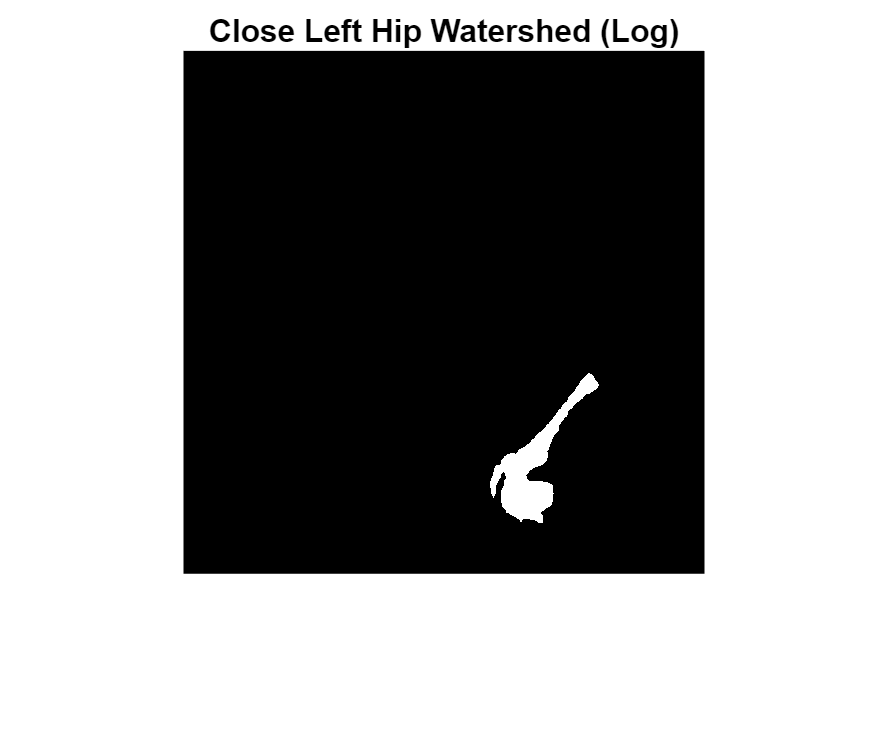


diskse = strel('disk',1);
leftHip_Close = imclose(leftHip,diskse);   % Eliminates edges and creates a solid figure
imshow(leftHip_Close)
title('Close Left Hip Watershed (Log)')

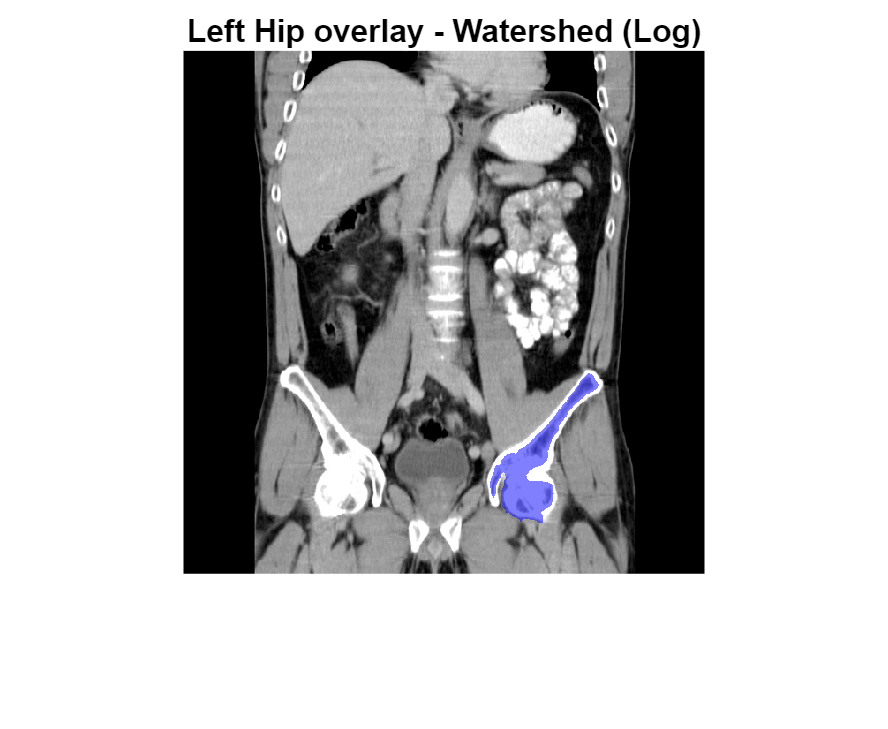


B = labeloverlay(f,leftHip_Close);
imshow(B)
title("Left Hip overlay - Watershed (Log)")

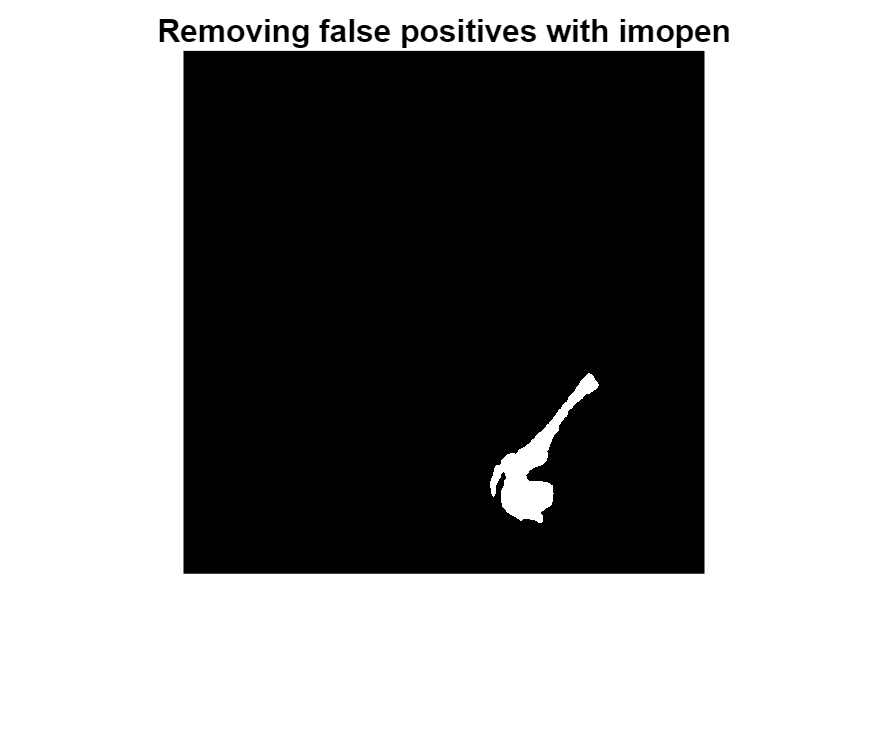


% Remove false positives with imopen
label_hip = imopen(leftHip_Close,diskse11);
imshow(label_hip)
title('Removing false positives with imopen')

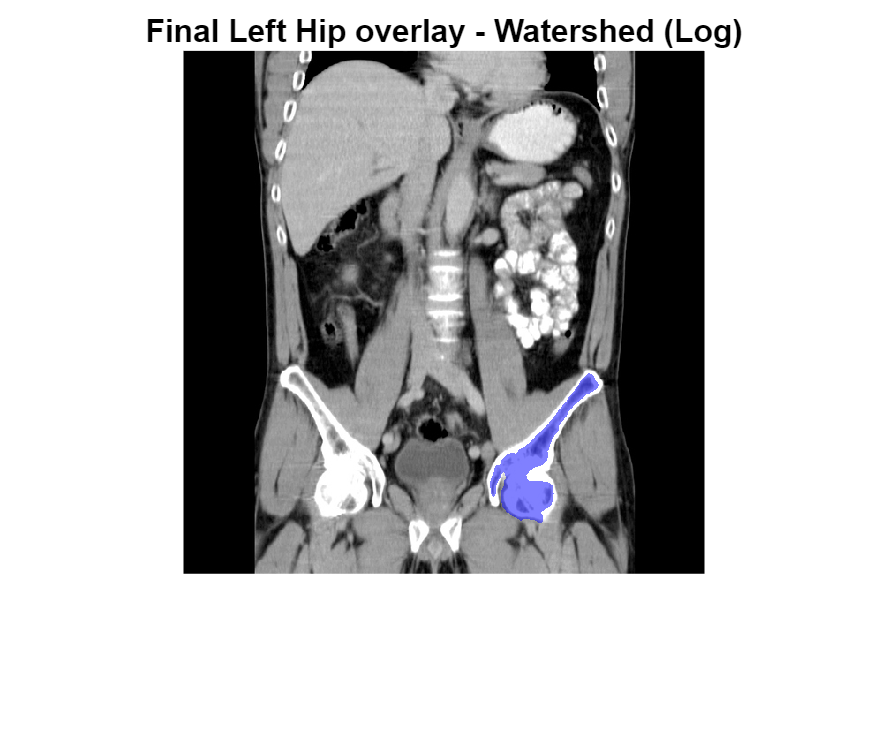


B = labeloverlay(f,label_hip);
imshow(B)
title("Final Left Hip overlay - Watershed (Log)")